
clear,clc;
warning('off','all');
%% params

% Wphi = 1        
% Wp = 1   

Wphi = 0       

Wphi = 0

Wp = 0

Wp = 0



condits = OSCmodel_asfunc(Wphi, Wp);

beg_manipulation = groupsummary(condits, {'cmp_beg'},'sum', {'corr_resp'} );
end_manipulation = groupsummary(condits, {'st_end'},'sum', {'corr_resp'} );

condits

condits = 27×8 table
       cmp_len              cmp_beg               st_end         st     ISI     com      C_fin       corr_resp
    ______________    ___________________    ________________    ___    ____    ___    __________    _________

    'comp shorter'    'early beginning'      'early ending'      540    1200    486         -0.29        1    
    'comp same'       'early beginning'      'early ending'      540    1200    540          -0.2        0    
    'comp longer'     'early beginning'      'early ending'      540    1200    594         -0.11        0    
    'comp shorter'    'early beginning'      'on-time ending'    600    1140    540          -0.2        1    
    'comp same'       'early beginning' 

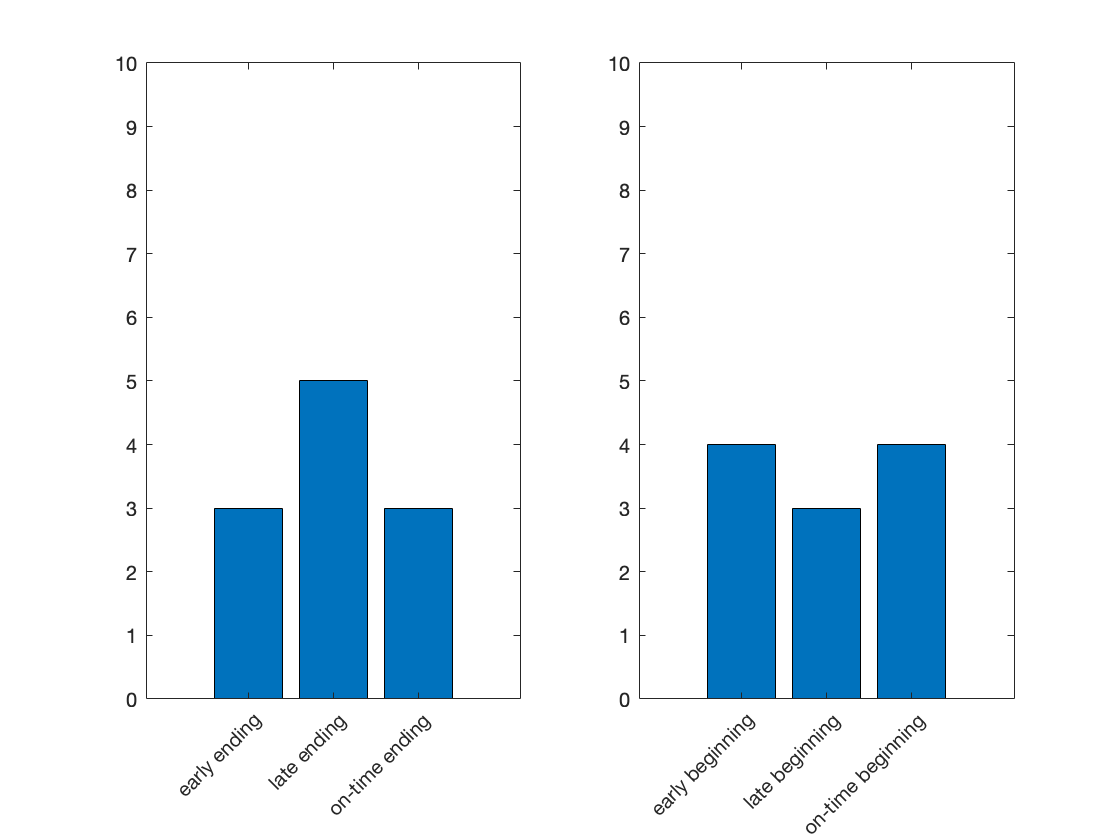


% plot
figure;
subplot(1,2,1)
bar(end_manipulation.sum_corr_resp); 
xticklabels(table2cell(end_manipulation(:,1)));xtickangle(45);
yline(10); %set(gca, 'FontSize', 14);

subplot(1,2,2)
bar(beg_manipulation.sum_corr_resp); 
xticklabels(table2cell(beg_manipulation(:,1)));xtickangle(45);
yline(10); %set(gca, 'FontSize', 14);